%% VIP Professional Development Session

data = readtable('sensor_data.csv');

head(data)

    Time_s_    Temperature_C_    Pressure_kPa_    Vibration_m_s_2_
    _______    ______________    _____________    ________________

       0            25.1             101.2              0.02      
       1            25.3             101.1              0.03      
       2            25.5               101              0.04      
       3            25.7             100.9              0.03      
       4              26             100.7              0.05      
       5            26.5             100.5              0.06      



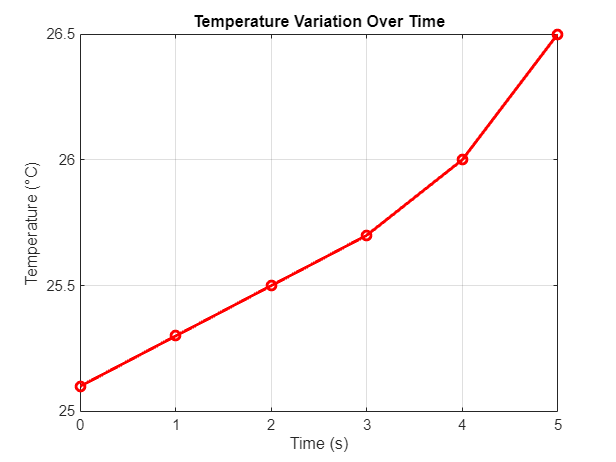

Time = data(:,1);
Temperature = data(:,2);
Pressure = data(:,3);
Vibration = data(:,4);
% plot Temperature vs time
plot(data.Time_s_, data.Temperature_C_, 'r-o', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Temperature (°C)');
title('Temperature Variation Over Time');
grid on;

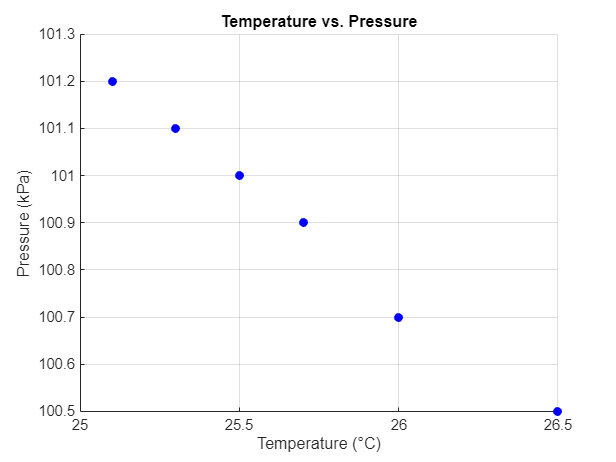

scatter(data.Temperature_C_, data.Pressure_kPa_, 'b', 'filled');
xlabel('Temperature (°C)');
ylabel('Pressure (kPa)');
title('Temperature vs. Pressure');
grid on;

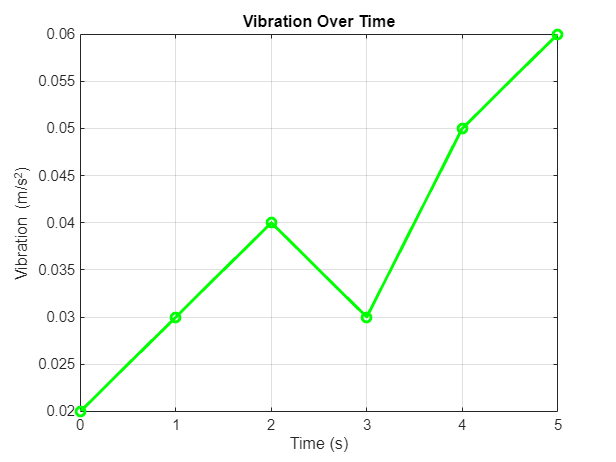

% finding the mean and standard deviation
mean_temp = mean(data.Temperature_C_);
std_temp = std(data.Temperature_C_);
% Finding maximum and minimum values
max_temp = max(data.Temperature_C_);
min_temp = min(data.Temperature_C_);

% Activity
mean_pressure = mean(data.Pressure_kPa_);
std_pressure = std(data.Pressure_kPa_);

plot(data.Time_s_, data.Vibration_m_s_2_, 'g-o', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Vibration (m/s^2)');
title('Vibration Over Time');
grid on;

[max_temp, max_index] = max(data.Temperature_C_);
time_max_temp = data.Time_s_(max_index);